## Q1. Demand modelling

A new policy is proposed in the UK which aims to affect daily commutes (travel-to-work journeys). The policy is defined as follows: 

• Discourage long commutes (≥ 10 km, one way), originating in a densely populated area i (mi ≥ 10,000), by introducing a daily 1 pence per km fee for any such trips. 

• Encourage long commutes (≥ 10 km, one way), originating in rural, sparsely populated areas (mi < 10,000), by providing a daily subsidy of £2 per trip. 

For the purpose of this analysis, you should assume that the UK is made up of a set of zones i, with populations mi , and pairwise distances di,j (km) between zones j ̸=i.

### a. Net-positive or Net-negative

The Radiation model is in the form:


$$T_{i,j} = T_i \frac{P_iP_j}{(P_i+S_{i,j})(P_i+P_j+S_{i,j})$$


T_i,j is the number of trips from i to j, T_i is the number of trips originating in i (a product of employment rate and population of the area), P is the population of the area, and S is the sum of the populations of areas within the circle centred at i extending to j not including the areas i and j.

Start by assessing current situation..

The total number of trips is therefore given by:


$$\sum T_{i,j} = \sum_{j=1}^n\sum_{i=1}^nT_i\frac{P_iP_j}{(P_i + S_{i,j})(P_i + P_j+S_{i,j})$$


where 


$$S_{i,j} = \sum_{k=1}^nP_k \vert (d_{k,i}\leq d_{i,j}, k \neq i, j , i \neq j)$$


The benefit to the UK treasury occurs for every pairing of origin-destination areas where the origin population is greater than or equal to 10000, and the distance between the pair is greater than 10km. For each of these events the fee is £0.01 multiplied by the distance and the number of trips.

And so the benefit B: (distance in kM)


$$B = \sum_{i=1}^n \sum_{j=1}^n 0.01 d_{i,j} T_{i,j}  |(d_{i,j} \geq 10, P_i \geq10000, i \neq j)
$$


The cost to the UK treasury is £2 multiplied by the number of trips where the distance is greater than 10km and the population of the origin area is less than or equal to 10000.

And so the cost C:


$$C = \sum_{i=1}^n \sum_{j=1}^n 2 T_{i,j} | (P_i < 10000, d_{i,j} \geq 10)$$


With T_i,j  and S_i,j defined as above.

The net cost is therefore B - C, where if this value is positive it is net-positive for the UK treasury.

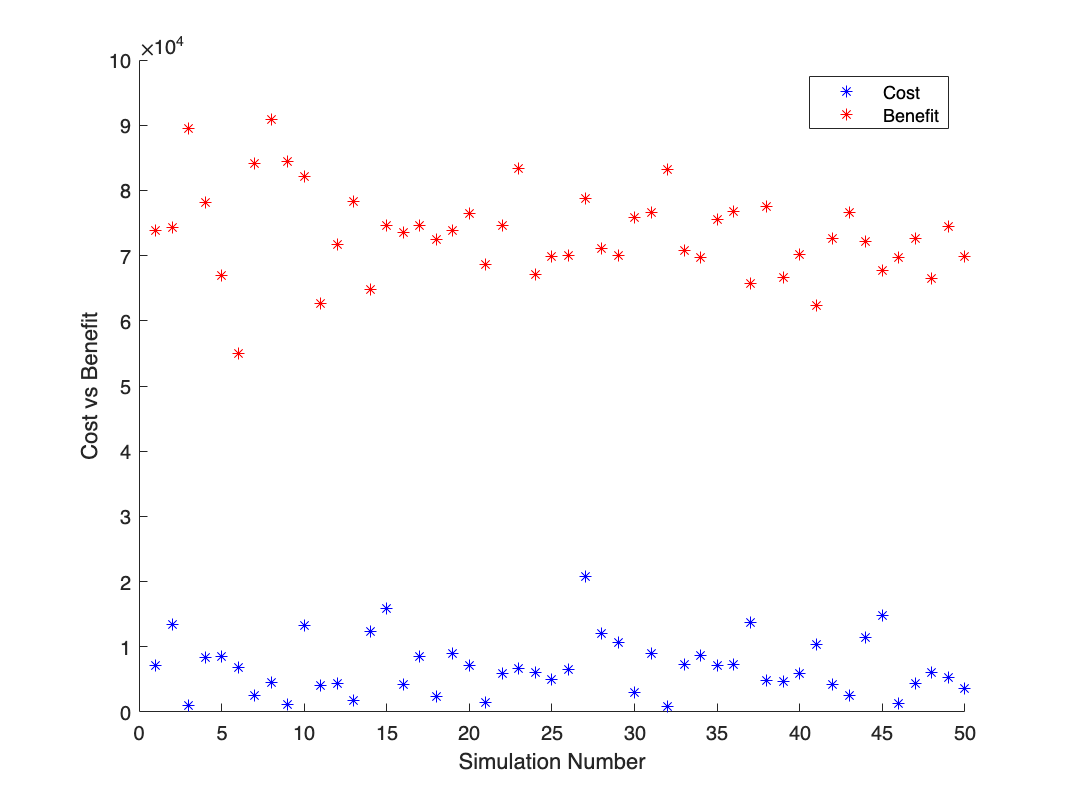

% run simulation n times
n = 50;
figure;
hold on
cost_v = [];
benefit_v = [];
for sim = 1:n
    % Define parameters
    numAreas = 50;  % Number of towns
    population = randi([1, 50000], 1, numAreas);  % Random population for each area
    distanceMatrix = randi([1, 100], numAreas, numAreas);  % Random distance matrix
    
    % Initialize T_ij matrix
    T_ij = zeros(numAreas, numAreas);
    
    % Calculate S_ij
    S_ij = zeros(numAreas, numAreas);
    for i = 1:numAreas
        for j = 1:numAreas
            if i ~= j
                S_ij(i, j) = sum(population(distanceMatrix(:, i) <= distanceMatrix(i, j) & (1:numAreas)' ~= i & (1:numAreas)' ~= j));
            end
        end
    end
    cost = 0;
    benefit = 0;
    % Calculate T_ij
    for i = 1:numAreas
        for j = 1:numAreas
            if i ~= j
                numerator = population(i) * population(j);
                denominator = (population(i) + S_ij(i, j)) * (population(i) + population(j) + S_ij(i, j));
                T_ij(i, j) = population(i) * numerator / denominator;
            end
        end
    end
    for i = 1:numAreas
        for j = 1:numAreas
            if population(i) >= 10000 && distanceMatrix(i, j) >= 10
                % Calculate benefit
                benefit = benefit + 0.01 * T_ij(i, j) * distanceMatrix(i,j);
            end
            
            if distanceMatrix(i, j) >= 10 && population(i) < 10000
                % Calculate cost
                cost = cost + 2 * T_ij(i, j);
            end
        end
    end

    cost_v(sim) = cost;
    benefit_v(sim) = benefit;
    
end
plot(1:sim,cost_v,'*',Color='b',DisplayName='Cost');
plot(1:sim,benefit_v,'*', Color='r', DisplayName='Benefit');
xlabel('Simulation Number')
ylabel('Cost vs Benefit')
legend

With this random silulation set-up it appears that the benefit is always > cost and so it is net-positive however this is not representative of the UK.

### b. Percentage of people affected by the policy

The percentage will be:


$$\frac{\sum T_{i,j} |(P_i\geq10000 , d_{i,j}\geq10) + T_{i,j} |(P_i<10000 , d_{i,j}\geq10)}{\sum T_{i,j}|(i\neq j )$$


This is the sum of all trips greater than 10km from densely populated areas, and the sum of all trips greater than 10km from rural areas, divided by the total number of trips occuring.

However, if considering the sum of all trips from both P  >= 10000 and P < 10000, this sum effects people from all population sizes, and the only dependency becomes the trip distance.


$$\frac{\sum T_{i,j} |d_{i,j}\geq10}{\sum T_{i,j}$$


(multiplied by 100)

% for the example
numer = 0;
totalTrips = sum(sum(T_ij));
for i = 1:numAreas
        for j = 1:numAreas
            if distanceMatrix(i, j) >= 10
                % numerator
                numer = numer + T_ij(i,j);
            end     
        end
end

% in this simulation
percentage_effected = (numer/totalTrips) * 100

percentage_effected = 26.0822

### c. Six city system


$$\matrix{
\text{City}    	&  \text{x} &  \text{y}& P_i
 \cr
A		& 0 			&0		&50000			 \cr
B		& 5 			&5		&20000			\cr C		& 10 			&0		&50000			\cr D	& 0 			&-7		&20000			\cr E		& -7			& -3		&18000			\cr F		& -12 			&6		&15000			\cr
}$$


#### i. How many trips originate in A and terminate in C

x = [0,5,10,0,-7,-12];
y = [0,5,0,-7,-3,6];
p = [50000, 20000, 50000, 20000, 18000, 15000];

% make a origin - destination distance matrix
d_ij = zeros(6,6);

for i = 1:length(x) % origin
    for j = 1:length(y) % destination
        x_dist = abs(x(i) - x(j));
        y_dist = abs(y(i) - y(j));
        d_ij(i,j) = sqrt(x_dist^2 + y_dist^2);
    end
end

% trips originating in A
employ = 0.755  % the national employment rate from ONS 2023

employ = 0.7550

T_a = p(1) * employ

T_a = 37750


% s term
S_a = 0;
for i = 1: length(d_ij)
    if d_ij(i,1) < d_ij(3,1) && i~=1  && i~=3 % exclude start/end
        S_a = S_a + p(i);
    end
end

T_ac = T_a*(p(1)*p(3))/((p(1)+ S_a)*(p(1)+p(3)+S_a));

% trips going from A to C:
round(T_ac)

ans = 5531

#### ii. What is the ratio of T_ac / T_ca

T_c = p(3) * employ

T_c = 37750


% s term
S_c = 0;
for i = 1: length(d_ij)
    if d_ij(i,3) < d_ij(1,3) && i~=1 && i~=3 % exclude start/end
        S_c = S_c + p(i);
    end
end
S_c

S_c = 20000


T_ca = T_c*(p(1)*p(3))/((p(3)+ S_c)*(p(1)+p(3)+S_c));

% ratio
ratio_ac_ca = T_ac / T_ca

ratio_ac_ca = 0.4923

More trips go from C to A than vice versa.